F = @(x,y) y.*sin(x)+x.*cos(y);

%DEPRECATED
Q = dblquad(F,pi,2*pi,0,pi)

Q = -9.8696

 %dblquad(f, xmin, xmax, ymin, ymax)
Q = integral2(F,pi,2*pi,0,pi)

Q = -9.8696

analitycznie

syms x y
int(int(y*sin(x)+x*cos(y), x, pi, 2*pi), y, 0, pi) 

$$ans = -\pi^{2}$$

Treść zadania 

f = @(x, y) x-x;
g = @(x, y) 8 - x.^2 - y.^2;

integral2(g, -2, 2, -2, 2);

Wykresig

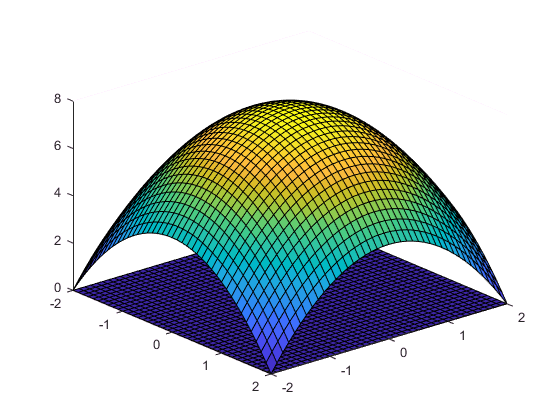

[X, Y] = meshgrid(-2:0.1:2, -2:0.1:2);
hold on;
surf(X, Y, f(X, Y));
surf(X, Y, g(X,Y));
view([50 30]);
hold off;